# Basics of 4-pulse DEER signal simulation (1)

#### Author: Luis Fabregas

This tutorial will cover the basics of dipolar signal simulation with the example of 4-pulse DEER.

## Preparing the components

In order to simualte a dipolar signal we require 3 basic components:

- Time-domain axis `t`

- Distance-domain axis `r`

- Distance distribution `P` or single distance r`single`

Let's start from the time-domain axis. In DeerAnalysis, all **time-domain **data must be given in **microseconds**, and negative times can be passed naturaly. We will construct a time-axis rangin from -0.5us to 4us with a resolution of 500 points.    

tmin = -0.5; %us
tmax = 4; %us
N = 500;

%Time-domain axis
t = linspace(tmin,tmax,N); %us

Next we will cosntruct the distance-domain axis. In DeerAnalysis, all **distance-domain** data must be given in **nanometers**, and only positive non-zero distances are allowed. We will consider a distance-axis ranging from 2nm to 6nm with a resolution of 400 points. 

rmin = 2; %nm
rmax = 6; %nm
N = 500;

%Time-domain axis
r = linspace(rmin,rmax,N); %nm

**NOTE: **In contrast to older versions, in DeerAnalysis the distance and time-domain dimensions are not required to be equal.

## Simulating dipolar evolution functions 

Dipolar evolution functions contain solely the dipolar modulation information (i.e. no modulation depth or background). All simulations are performed by the `dipolarsignal` function. We will treat two cases: 

#### Simulating a single distance signal

First let's simulate a dipolar evolution function corresponding to a single distance (e.g. 4nm). In such cases we only need to pass the time-axis `t` and the single distance `rsingle` to the `dipolarsignal` function. 

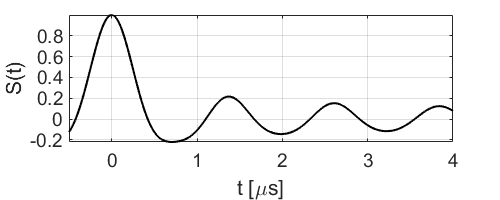

rsingle = 4; %nm

%Simulate dipolar evolution function
S = dipolarsignal(t,rsingle);

%Plot
figure('position',[0 0 500 200])
plot(t,S,'k','Linewidth',1.5)
set(gca,'fontsize',14)
axis tight, grid on
xlabel('t [\mus]'),ylabel('S(t)')

#### Simulating a distance distribution signal

Now instead of taking a single distance we will consider a Gaussian distribution of signals centered about 4nm with a width of 0.8nm.

%Generate a distance distribution
rmean = 4; %nm
width = 0.8; %nm
P = rd_onegaussian(r,[rmean width]);

Now in order to simulate the corresponding dipolar signal we will need to pass not only the time-axis but the distance distribution and the distance-axis on which it is defined. 

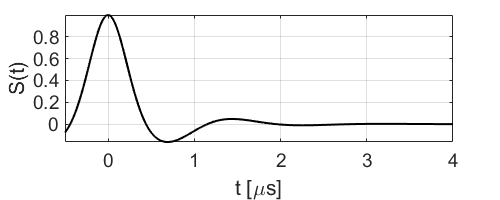

%Simulate dipolar evolution function
S = dipolarsignal(t,r,P);

%Plot
figure('position',[0 0 500 200])
plot(t,S,'k','Linewidth',1.5)
set(gca,'fontsize',14)
axis tight, grid on
xlabel('t [\mus]'),ylabel('S(t)')